# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.11 Spotlight SAR Doppler Bandwidth

## Calculate the Doppler bandwidth

$B_d =2f_D =\frac{4v}{\lambda \;}\sin \left(\theta_{\max } \right)\;\;\left(\textrm{Hz}\right)$   Equation (2.38)

$B_D =\frac{2\;v\;L_{\textrm{sa}} \;}{\lambda \;R_{0\;} }\;\left(\textrm{Hz}\right)$     Equation (2.39)

% Clear the workspace
clear

% Velocity (m/s)
velocity = linspace(50, 300, 1e3);

% Operating frequency (Hz)
operating_frequency = 14e9;

% Synthetic aperture length (m)
aperture_length = 100;

% Range to image center (m)
slant_range = [10e3, 30e3, 50e3];

% Calculate the Doppler bandwidth (Hz)
for i = 1:length(slant_range)
    doppler_bandwidth(i,:) = spotlight_doppler_bandwidth(velocity, aperture_length, operating_frequency, slant_range(i));
end

## Plot the results

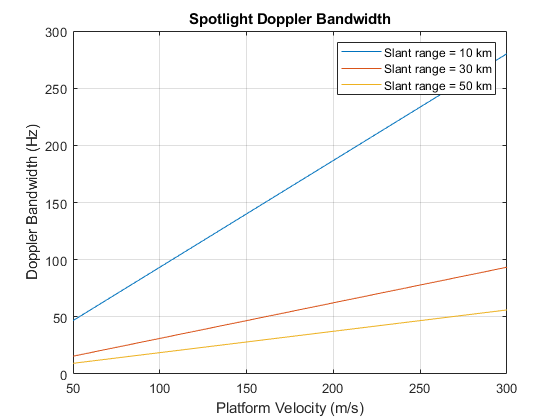

figure;
plot(velocity, doppler_bandwidth);
xlabel('Platform Velocity (m/s)')
ylabel('Doppler Bandwidth (Hz)');
title('Spotlight Doppler Bandwidth')
grid on
legend('Slant range = 10 km', 'Slant range = 30 km', 'Slant range = 50 km')